repeatTimes = 2; % Количество повторений выполнения кода

from = 50; % Начальная размерность таблицы
to = 1500; % Конечная размерность таблицы
step = 50; % Шаг изменения размерности

n_values = from:step:to; % Размерности таблицы

% Пустые вектора для средних времен выполнения
avgTimesVogel = zeros(size(n_values));
avgTimesNW = zeros(size(n_values));
avgTimesMinRate = zeros(size(n_values));

% Пустые вектора для среднего количества шагов выполнения
avgStepsVogel = zeros(size(n_values));
avgStepsNW = zeros(size(n_values));
avgStepsMinRate = zeros(size(n_values));

% Пустые вектора для среднего значения суммы транспортных расходов
avgCostVogel   = zeros(size(n_values));
avgCostNW      = zeros(size(n_values));
avgCostMinRate = zeros(size(n_values));
avgCostLinprog = zeros(size(n_values));

for q=1:length(n_values) % Итерация по всем размерностям
    n = n_values(q); % Получение текущей размерности
    fprintf('\nn = %d',n);
    fprintf('');

    % Инициализация нулями массива для шагов выполнения программы
    stepsVogel   = zeros(1,repeatTimes);
    stepsNW      = zeros(1,repeatTimes);
    stepsMinRate = zeros(1,repeatTimes);

    % Инициализация нулями массива для времени выполнения программы
    timesVogel   = zeros(1,repeatTimes);
    timesNW      = zeros(1,repeatTimes);
    timesMinRate = zeros(1,repeatTimes);

    % Инициализация нулями массива для суммы транспортных расходов
    costVogelArr   = zeros(1,repeatTimes);
    costNWArr      = zeros(1,repeatTimes);
    costMinRateArr = zeros(1,repeatTimes);
    costLinprogArr = zeros(1,repeatTimes);

    bestTimeVogel = inf;
    bestTimeNW = inf;
    bestTimeMinRate = inf;

    worstTimeVogel = -inf;
    worstTimeNW = -inf;
    worstTimeMinRate = -inf;

    for k=1:repeatTimes % Решаем задачу repeatTimes-раз
        [C, supply, needs] = generateModel(n); % Генерируем тестовые данные

        tic; % Засекаем время
        [vogelsCost, vogelsSteps] = vogelsMethod(C, supply, needs);
        timesVogel(k) = toc; % Сохраняем текущее время

        tic; % Засекаем время
        [northWestCost, northWestSteps] = norhWestMethod(C, supply, needs);
        timesNW(k) = toc; % Сохраняем текущее время

        tic; % Засекаем время
        [minRateCost, minRateSteps] = minRateMethod(C, supply, needs);
        timesMinRate(k) = toc; % Сохраняем текущее время

        % Сохраняем текущее количество шагов
        stepsVogel(k)   = vogelsSteps;
        stepsNW(k)      = northWestSteps;
        stepsMinRate(k) = minRateSteps;

        % Сохраняем текущее значение суммы транспортных расходов
        costVogelArr(k)   = vogelsCost;
        costNWArr(k)      = northWestCost;
        costMinRateArr(k) = minRateCost;
        costLinprogArr(k) = solveTP(C, supply, needs);

        % Переназначем лучшее и худшее время
        if(timesVogel(k) < bestTimeVogel)
            bestTimeVogel = timesVogel(k);
        end
        if(timesVogel(k) > worstTimeVogel)
            worstTimeVogel = timesVogel(k);
        end

        if(timesNW(k) < bestTimeNW)
            bestTimeNW = timesNW(k);
        end
        if(timesNW(k) > worstTimeNW)
            worstTimeNW = timesNW(k);
        end

        if(timesMinRate(k) < bestTimeMinRate)
            bestTimeMinRate = timesMinRate(k);
        end
        if (timesMinRate(k) > worstTimeMinRate)
            worstTimeMinRate = timesMinRate(k);
        end
    end

    % Считаем среднее время за repeatTimes-прогонов
    avgTimesVogel(q) = mean(timesVogel);
    avgTimesNW(q) = mean(timesNW);
    avgTimesMinRate(q) = mean(timesMinRate);

    % Считаем среднее количество шагов за repeatTimes-прогонов
    avgStepsVogel(q) = mean(stepsVogel);
    avgStepsNW(q) = mean(stepsNW);
    avgStepsMinRate(q) = mean(stepsMinRate);

    % Считаем среднее значение суммы транспортных расходов за repeatTimes-прогонов
    avgCostVogel(q)   = mean(costVogelArr);
    avgCostNW(q)      = mean(costNWArr);
    avgCostMinRate(q) = mean(costMinRateArr);
    avgCostLinprog(q) = mean(costLinprogArr);

    disp('Метод Фогеля:')
    fprintf('  1) Среднее количество шагов за прогон: %.1f',avgStepsVogel(q));
    fprintf('  2) Лучшее время выполнения кода за прогон: %.4f секунд\n', bestTimeVogel);
    fprintf('  3) Среднее время выполнения кода за прогон: %.4f секунд\n', avgTimesVogel(q));
    fprintf('  4) Худшее время выполнения кода за прогон: %.4f секунд\n', worstTimeVogel);

    disp('Метод с-з угла:')
    fprintf('  1) Среднее количество шагов за прогон: %.1f',avgStepsNW(q));
    fprintf('  2) Лучшее время выполнения кода за прогон: %.4f секунд\n', bestTimeNW);
    fprintf('  3) Среднее время выполнения кода за прогон: %.4f секунд\n', avgTimesNW(q));
    fprintf('  4) Худшее время выполнения кода за прогон: %.4f секунд\n', worstTimeNW);

    disp('Метод минимального элемента:')
    fprintf('  1) Среднее количество шагов за прогон: %.1f',avgStepsMinRate(q));
    fprintf('  2) Лучшее время выполнения кода за прогон: %.4f секунд\n', bestTimeMinRate);
    fprintf('  3) Среднее время выполнения кода за прогон: %.4f секунд\n', avgTimesMinRate(q));
    fprintf('  4) Худшее время выполнения кода за прогон: %.4f секунд\n', worstTimeMinRate);
end


n = 50

Метод Фогеля:


  1) Среднее количество шагов за прогон: 98.0

  2) Лучшее время выполнения кода за прогон: 0.0072 секунд


  3) Среднее время выполнения кода за прогон: 0.0080 секунд


  4) Худшее время выполнения кода за прогон: 0.0088 секунд


Метод с-з угла:


  1) Среднее количество шагов за прогон: 99.0

  2) Лучшее время выполнения кода за прогон: 0.0002 секунд


  3) Среднее время выполнения кода за прогон: 0.0008 секунд


  4) Худшее время выполнения кода за прогон: 0.0014 секунд


Метод минимального элемента:


  1) Среднее количество шагов за прогон: 98.5

  2) Лучшее время выполнения кода за прогон: 0.0015 секунд


  3) Среднее время выполнения кода за прогон: 0.0030 секунд


  4) Худшее время выполнения кода за прогон: 0.0044 секунд



n = 100

Метод Фогеля:


  1) Среднее количество шагов за прогон: 198.5

  2) Лучшее время выполнения кода за прогон: 0.0463 секунд


  3) Среднее время выполнения кода за прогон: 0.0476 секунд


  4) Худшее время выполнения кода за прогон: 0.0488 секунд


Метод с-з угла:


  1) Среднее количество шагов за прогон: 199.0

  2) Лучшее время выполнения кода за прогон: 0.0002 секунд


  3) Среднее время выполнения кода за прогон: 0.0003 секунд


  4) Худшее время выполнения кода за прогон: 0.0003 секунд


Метод минимального элемента:


  1) Среднее количество шагов за прогон: 197.0

  2) Лучшее время выполнения кода за прогон: 0.0012 секунд


  3) Среднее время выполнения кода за прогон: 0.0012 секунд


  4) Худшее время выполнения кода за прогон: 0.0012 секунд



n = 150

Метод Фогеля:


  1) Среднее количество шагов за прогон: 298.0

  2) Лучшее время выполнения кода за прогон: 0.1514 секунд


  3) Среднее время выполнения кода за прогон: 0.1532 секунд


  4) Худшее время выполнения кода за прогон: 0.1550 секунд


Метод с-з угла:


  1) Среднее количество шагов за прогон: 299.0

  2) Лучшее время выполнения кода за прогон: 0.0002 секунд


  3) Среднее время выполнения кода за прогон: 0.0004 секунд


  4) Худшее время выполнения кода за прогон: 0.0005 секунд


Метод минимального элемента:


  1) Среднее количество шагов за прогон: 296.0

  2) Лучшее время выполнения кода за прогон: 0.0028 секунд


  3) Среднее время выполнения кода за прогон: 0.0033 секунд


  4) Худшее время выполнения кода за прогон: 0.0038 секунд



n = 200

Метод Фогеля:


  1) Среднее количество шагов за прогон: 396.5

  2) Лучшее время выполнения кода за прогон: 0.3418 секунд


  3) Среднее время выполнения кода за прогон: 0.3505 секунд


  4) Худшее время выполнения кода за прогон: 0.3592 секунд


Метод с-з угла:


  1) Среднее количество шагов за прогон: 399.0

  2) Лучшее время выполнения кода за прогон: 0.0002 секунд


  3) Среднее время выполнения кода за прогон: 0.0003 секунд


  4) Худшее время выполнения кода за прогон: 0.0003 секунд


Метод минимального элемента:


  1) Среднее количество шагов за прогон: 396.0

  2) Лучшее время выполнения кода за прогон: 0.0054 секунд


  3) Среднее время выполнения кода за прогон: 0.0056 секунд


  4) Худшее время выполнения кода за прогон: 0.0058 секунд



n = 250

Метод Фогеля:


  1) Среднее количество шагов за прогон: 496.0

  2) Лучшее время выполнения кода за прогон: 0.6796 секунд


  3) Среднее время выполнения кода за прогон: 0.6837 секунд


  4) Худшее время выполнения кода за прогон: 0.6888 секунд


Метод с-з угла:


  1) Среднее количество шагов за прогон: 499.0

  2) Лучшее время выполнения кода за прогон: 0.0003 секунд


  3) Среднее время выполнения кода за прогон: 0.0004 секунд


  4) Худшее время выполнения кода за прогон: 0.0004 секунд


Метод минимального элемента:


  1) Среднее количество шагов за прогон: 495.0

  2) Лучшее время выполнения кода за прогон: 0.0099 секунд


  3) Среднее время выполнения кода за прогон: 0.0109 секунд


  4) Худшее время выполнения кода за прогон: 0.0118 секунд



% Построение графиков
headTitle1 = 'Зависимость времени выполнения от размерности';
headTitle2 = 'Зависимость количества шагов от размерности';

yLabel1 = 'Время выполнения (секунды)';
yLabel2 = 'Количество шагов';

legend1 = 'Среднее время выполнения';
legend2 = 'Среднее количество шагов';

disp("Метод Фогеля");

Метод Фогеля


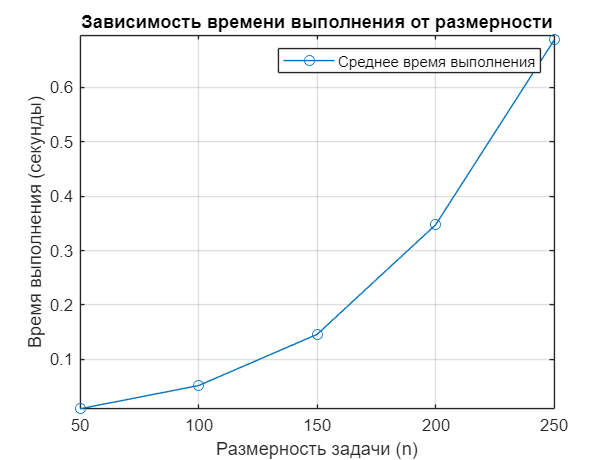

plotGraph(n_values, avgTimesVogel, headTitle1, yLabel1, legend1);

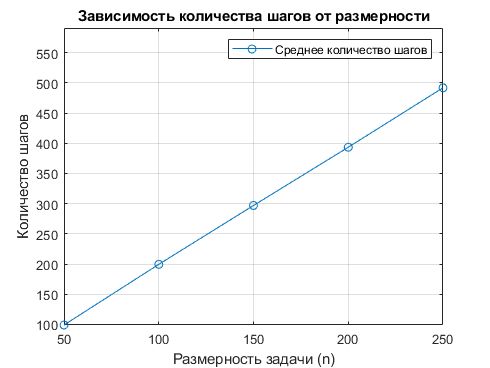

plotGraph(n_values,  avgStepsVogel, headTitle2, yLabel2, legend2);


disp("Метод Северо-западного угла");

Метод Северо-западного угла


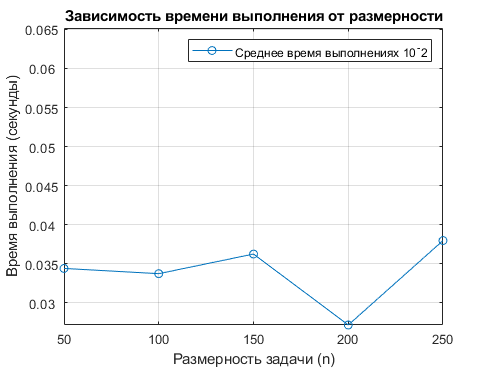

%plotGraph(n_values, avgTimesNW, 0.1, headTitle1, yLabel1, legend1);

% Из-за того, что метод С-з угла выполняется слишком быстро - надо
% масштабировать график по OY в 100 раз
figure;
plot(n_values, avgTimesNW, '-o');
xlabel('Размерность задачи (n)');
ylabel(yLabel1);
title(headTitle1);
ylim([min(avgTimesNW), max(avgTimesNW)+min(avgTimesNW)]);
legend([legend1 'x 10^-2']);

yticks = get(gca, 'YTick');
yticklabels = yticks * 10^2; % Масштаб по OY
set(gca, 'YTickLabel', yticklabels); 

grid on;

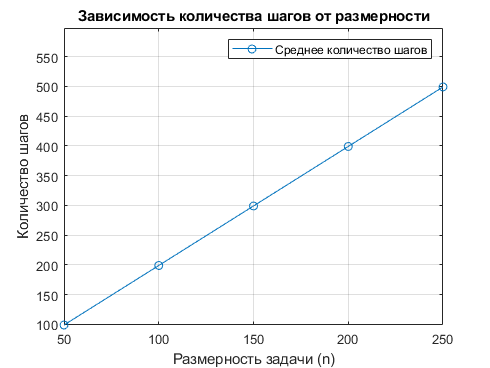

plotGraph(n_values,  avgStepsNW, headTitle2, yLabel2, legend2);


disp("Метод Минимального элемента");

Метод Минимального элемента


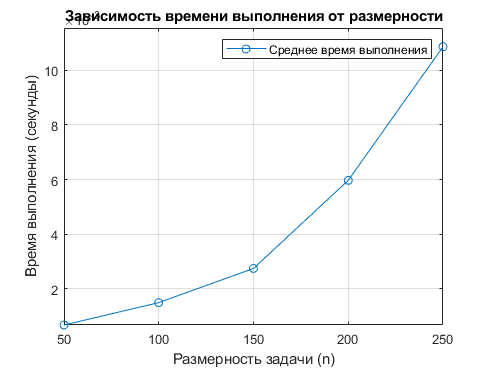

plotGraph(n_values, avgTimesMinRate, headTitle1, yLabel1, legend1);

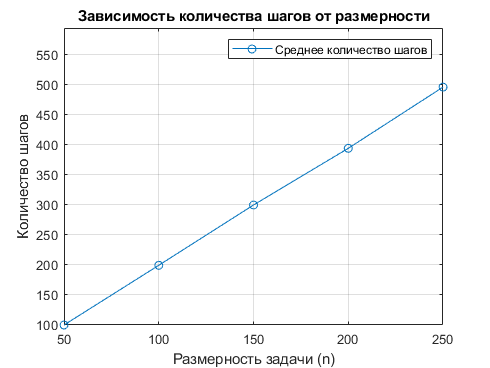

plotGraph(n_values,  avgStepsMinRate, headTitle2, yLabel2, legend2);

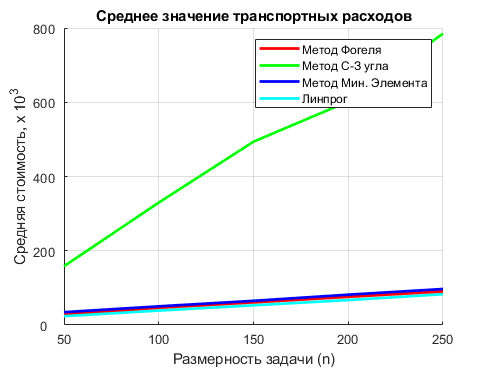


a = 'Метод Фогеля';
b = 'Метод С-З угла';
c = 'Метод Мин. Элемента';
d = 'Линпрог';

headTitle3 = 'Среднее значение транспортных расходов';
yLabel3 = 'Средняя стоимость, x 10^3';
plotMultipleGraph(n_values, avgCostVogel, avgCostNW, avgCostMinRate, avgCostLinprog, headTitle3, yLabel3, a, b, c, d);

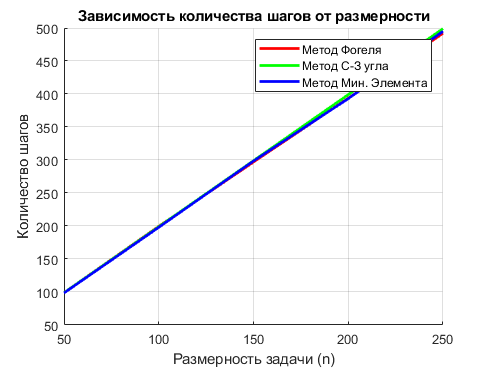

plotMultipleGraph(n_values, avgStepsVogel, avgStepsNW, avgStepsMinRate, [], headTitle2, yLabel2, a, b, c, d);

function plotGraph(x, y, headTitle, yLabel, lgnd)
figure; % Создаем новое окно
plot(x, y, '-o'); % Строим график с символом 'o' в значениях
xlabel('Размерность задачи (n)');
ylabel(yLabel);
title(headTitle); % Название 
ylim([min(y), max(y)+min(y)]); % Предел по OY от минимального значения y до максимального + минимальное
legend(lgnd); 
grid on; % Включаем сетку
end

function plotMultipleGraph(x, y1, y2, y3, y4, headTitle, yLabel, lgndA, lgndB, lgndC, lgndD)
figure;
grid on;
hold on;
title(headTitle);
ylabel(yLabel);
xlabel('Размерность задачи (n)');
plot(x, y1, '-r', 'LineWidth', 2);
plot(x, y2, '-g', 'LineWidth', 2);
plot(x, y3, '-b', 'LineWidth', 2);

if size(y4) == 0
    legend(lgndA, lgndB, lgndC);
else
    plot(x, y4, '-c', 'LineWidth', 2);
    legend(lgndA, lgndB, lgndC, lgndD);

    yticks = get(gca, 'YTick');
    yticklabels = yticks / 10^3;
    set(gca, 'YTickLabel', yticklabels);
end

hold off;
end